
%第三次作业 用bp神经网络实现字母识别
%只识别A,B,C,D
clc, clear, close all;
%输入为：图片
%输出为：字母


%图像预处理
%导入数据集
load('data1.mat');

%取训练样本
input=x

input =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     1     0     0     0     0     

target=d

target =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    


% newff 函数在2010b 之后已经弃用，现用 feedforwardnet (fitnet) 函数
% net = newff([0 10],[5 1],{'tansig' 'purelin'});
%sigmoid函数也叫Logistic函数，用于隐层神经元输出，取值范围为(0,1)，



% 创建网络2-5-10-4
tranFcn = 'traingda'; % 选择训练函数（学习规则）
hiddenLayer1Size = 5; % 第一层隐含层神经元的数目
hiddenLayer2Size=10;%第二层隐含层神经元的数目
net = feedforwardnet([hiddenLayer1Size,hiddenLayer2Size],tranFcn);



% 网络参数设置
net.layers{1}.transferFcn = 'logsig'; % 第一层隐含层的激活函数
net.layers{2}.transferFcn='tansig';%第二层隐含层的激活函数
net.layers{3}.transferFcn = 'purelin'; % 输出层的激活函数
net.trainparam.show = 50; % 每次循环50次
net.trainParam.epochs = 500; % 最大循环500次
net.trainparam.goal = 0.01; % 期望目标误差最小值



% 初始网络预测
%Configure：配置网络输入和输出,以达到最好的匹配输入和目标数据
net = configure(net,input,target);
pred1 = net(input)

pred1 =     0.6052    0.7368   -0.2954   -0.4058   -0.6812   -0.4775   -0.9026   -0.3324    0.7530    1.0261   -0.2200   -0.3573   -0.4636    0.9512    0.9803    0.8709    0.9319   -0.1051   -0.8312    1.0025    0.6539    0.9623    0.7291   -0.0303   -0.2804    0.3527    0.3107    0.7060    0.6104   -0.3783    0.5544    0.7998    0.7604    0.5175    0.9132    0.9254    0.9938    0.9783    0.6558    0.9997   -0.3951    0.9484    0.9745    0.9584    0.8297    0.9349    1.0595    1.0344    0.6836   -0.2232
    2.0702    1.4250    1.7635    2.1180    1.8868    1.8792    1.6942    1.8545    2.8148    2.4641    2.1669    1.7093    1.6616    1.8030    2.0425    1.6463    1.6454    2.3096    1.7685    2.0404    1.6333    1.8113    0.5275    2.1016    2.0948    2.6596    0.6241    2.5182    1.6112    2.2098    2.5542    2.7000    2.6776    1.3544    1.5867    1.7973    2.0701    1.9222    2.3161    2.0301    1.1281    1.6879    1.3758    1.7485    0.5440    1.6291    1.6938    2.4259    2.1454 

%pred1为所对应的input的初始网络预测值



% 训练网络并预测
net = train(net, input, target);
pred2 = net(input)

pred2 =     0.7718    0.6135    0.7380    0.7737    0.7602    0.8558    0.7790    0.8311    0.9382    0.7551    0.7900    0.7730    0.7782    0.6549    0.7619    0.8424    0.7572    0.7856    0.9360    0.6375    0.5685    0.7648    0.9559    0.8451    0.7783    0.7557    0.7602    0.5885    0.6148    0.5495    0.7370    0.7622    0.7952    0.7797    0.7772    0.7338    0.8850    0.1591    0.1274    0.4920   -0.2011    0.1425    0.2124    0.5697    0.5109    0.1660    0.1740    0.5953    0.1991    0.4325
   -0.0734    0.1311   -0.0935   -0.0191    0.0767    0.0253   -0.0742   -0.0081   -0.0576    0.0281   -0.1213   -0.0957   -0.1092   -0.0669   -0.0562   -0.0373   -0.0588   -0.0932    0.0270   -0.0579   -0.0131    0.0135    0.2395   -0.0028   -0.0713   -0.0748   -0.0637   -0.0595   -0.0637    0.4035   -0.0348   -0.0693   -0.1212   -0.0868   -0.0169   -0.0608   -0.0786    0.7920    0.9451   -0.0041   -0.1449    0.7518    0.7933    0.8854    0.6623    0.7474    0.7354    0.9220    0.9042 

%pred2为所对应的input的训练后网络预测值



save('net1.mat','net');       % 将网络net保存为.mat文件，后面可直接调用

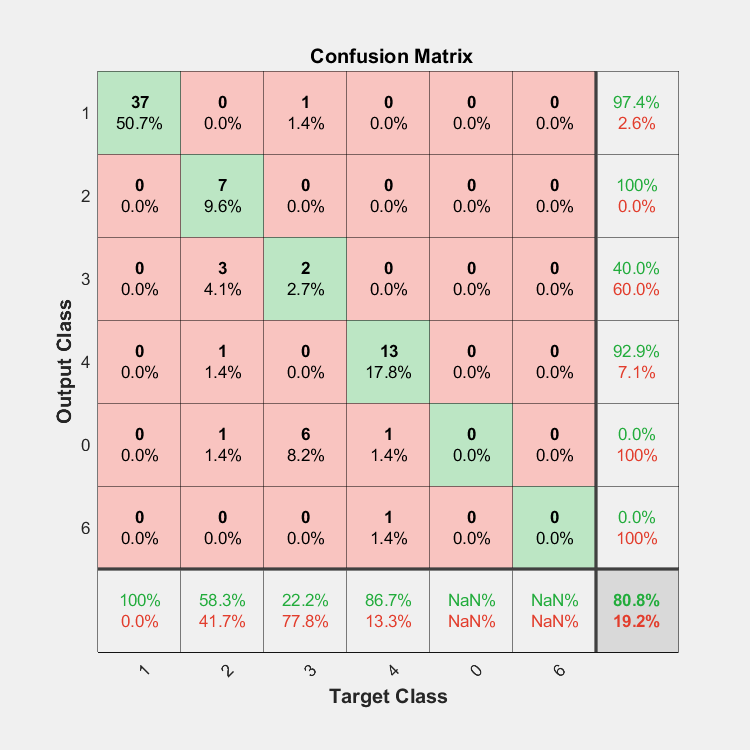




load('net1.mat');     % 导入之前保存的网络 

%画图
%1,2,3,4分别代表A,B,C,D
y=sim(net,input);
y=round(y);
%画出混淆矩阵
y2=zeros(1,73);
t=zeros(1,73);
for j=1:73
    m=0;n=0;
    for i=1:4
        m=m+y(i,j)*i;
        n=n+i*target(i,j);
    end
    y2(j)=m;
    t(j)=n;
end
t=categorical(t);
y=categorical(y2);
figure(1)
plotconfusion(t,y);         



load('net1.mat');     % 导入之前保存的网络
%预测函数
fprintf('请输入测试数据x3');

请输入测试数据x3

x3=input(:,7);
fprintf('输出测试结果y3');

输出测试结果y3

y3=sim(net,x3)

y3 =     0.7790
   -0.0742
    0.1951
   -0.0714


target(:,7)

ans =      1
     0
     0
     0
